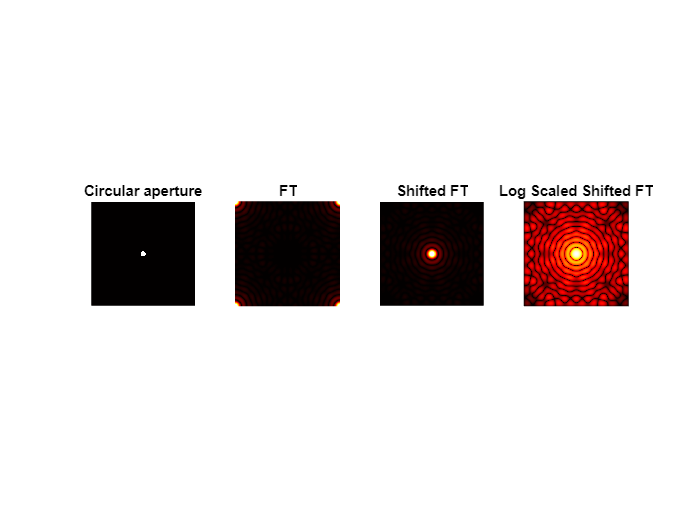

%Activity 1: Familiarization with Discrete FT

%circular aperture
N = 400;
x = linspace(-1, 1, N);
y = x;
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);
A = zeros(size(R));                 
A(R < 0.05) = 1.0;

FA = fft2(A);
FAshift = fftshift(FA);
FAshiftlog = rescale(log(abs(fftshift(FA))+1), 0,256); 

%plotting
figure;
subplot(1,4,1);imshow(A); title('Circular aperture');
subplot(1,4,2); image(abs(FA)); title('FT'); axis square; axis off;
subplot(1,4,3); image(abs(FAshift)); title('Shifted FT'); axis square; axis off;
subplot(1,4,4); imagesc(abs(FAshiftlog)); title('Log Scaled Shifted FT'); axis square; axis off; colormap hot;

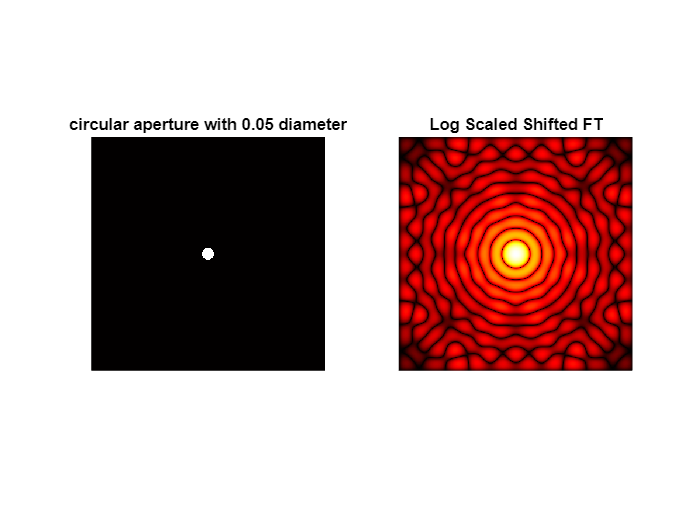

%circular aperture with 0.05 diameter
N = 400;
x = linspace(-1, 1, N);
y = x;
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);
A = zeros(size(R));                 
A(R < 0.05) = 1.0;

FA = fft2(A);
FAshift = fftshift(FA);
FAshiftlog = rescale(log(abs(fftshift(FA))+1), 0,256); 

%plotting
figure;
subplot(1,2,1);imshow(A); title('circular aperture with 0.05 diameter');
subplot(1,2,2); imagesc(abs(FAshiftlog)); title('Log Scaled Shifted FT'); axis square; axis off; colormap hot;

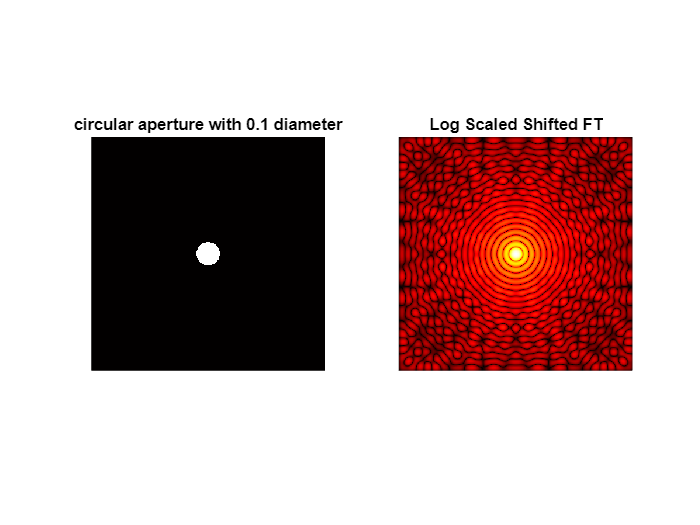

%circular aperture with 0.1 aperture
N = 400;
x = linspace(-1, 1, N);
y = x;
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);
A = zeros(size(R));                 
A(R < 0.1) = 1.0;

FA = fft2(A);
FAshift = fftshift(FA);
FAshiftlog = rescale(log(abs(fftshift(FA))+1), 0,256); 

%plotting
figure;
subplot(1,2,1);imshow(A); title('circular aperture with 0.1 diameter');
subplot(1,2,2); imagesc(abs(FAshiftlog)); title('Log Scaled Shifted FT'); axis square; axis off; colormap hot;

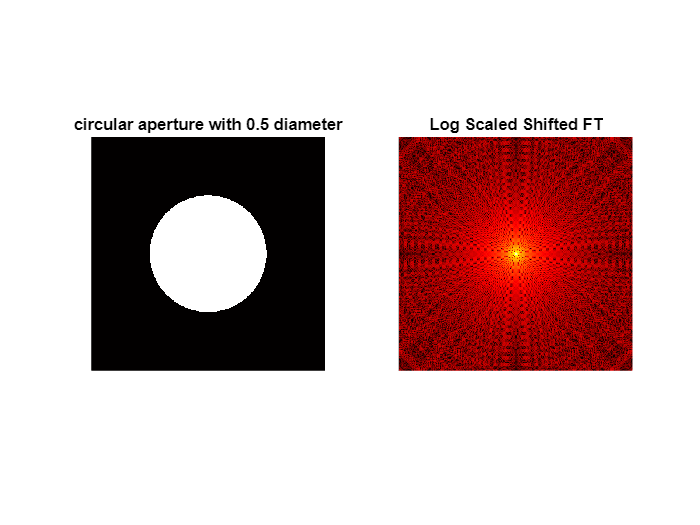

%circular aperture with 0.5 diameter
N = 400;
x = linspace(-1, 1, N);
y = x;
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);
A = zeros(size(R));                 
A(R < 0.5) = 1.0;

FA = fft2(A);
FAshift = fftshift(FA);
FAshiftlog = rescale(log(abs(fftshift(FA))+1), 0,256); 

%plotting
figure;
subplot(1,2,1);imshow(A); title('circular aperture with 0.5 diameter');
subplot(1,2,2); imagesc(abs(FAshiftlog)); title('Log Scaled Shifted FT'); axis square; axis off; colormap hot;

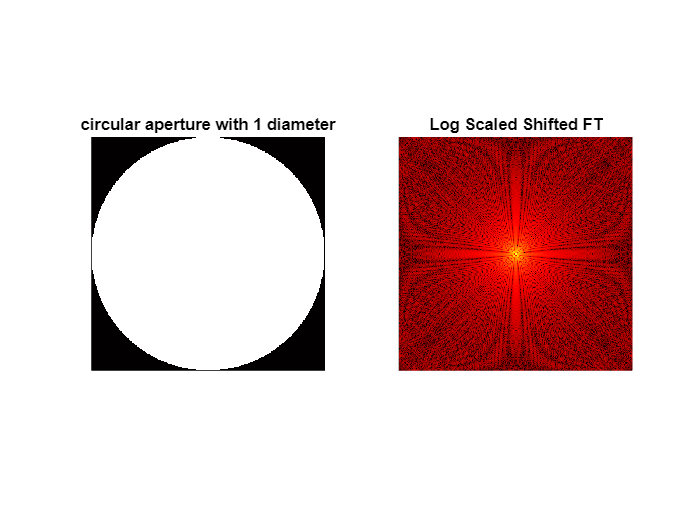


%circular aperture with 1 diameter
N = 400;
x = linspace(-1, 1, N);
y = x;
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);
A = zeros(size(R));                 
A(R < 1) = 1.0;

FA = fft2(A);
FAshift = fftshift(FA);
FAshiftlog = rescale(log(abs(fftshift(FA))+1), 0,256); 

%plotting
figure;
subplot(1,2,1);imshow(A); title('circular aperture with 1 diameter');
subplot(1,2,2); imagesc(abs(FAshiftlog)); title('Log Scaled Shifted FT'); axis square; axis off; colormap hot;

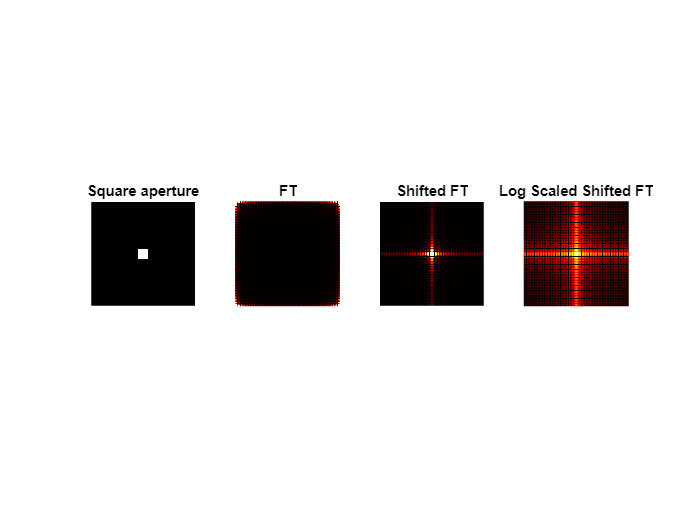

%square aperture
N = 400;
x = linspace(-1, 1, N);
y = x;
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);
A = zeros(size(R));
A(abs(X) < 0.1 & abs(Y) < 0.1) = 1.0;

FA = fft2(A);
FAshift = fftshift(FA);
FAshiftlog = rescale(log(abs(fftshift(FA))+1), 0,256); 

%plotting
figure;
subplot(1,4,1);imshow(A); title('Square aperture');
subplot(1,4,2); image(abs(FA)); title('FT'); axis square; axis off;
subplot(1,4,3); image(abs(FAshift)); title('Shifted FT'); axis square; axis off;
subplot(1,4,4); imagesc(abs(FAshiftlog)); title('Log Scaled Shifted FT'); axis square; axis off; colormap hot;

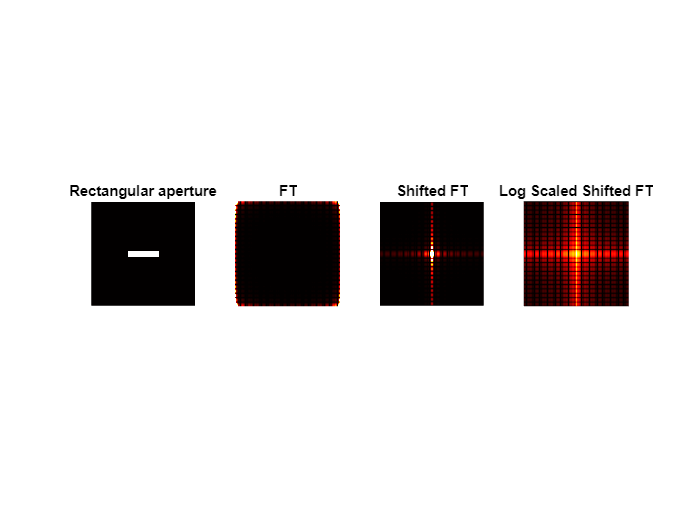

%rectangular aperture
N = 400;
x = linspace(-1, 1, N);
y = linspace(-0.5, 0.5, N);
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);
A = zeros(size(R));
A(abs(X) < 0.3 & abs(Y) < 0.03) = 1.0;

FA = fft2(A);
FAshift = fftshift(FA);
FAshiftlog = rescale(log(abs(fftshift(FA))+1), 0,256); 

%plotting
figure;
subplot(1,4,1);imshow(A); title('Rectangular aperture');
subplot(1,4,2); image(abs(FA)); title('FT'); axis square; axis off;
subplot(1,4,3); image(abs(FAshift)); title('Shifted FT'); axis square; axis off;
subplot(1,4,4); imagesc(abs(FAshiftlog)); title('Log Scaled Shifted FT'); axis square; axis off; colormap hot;

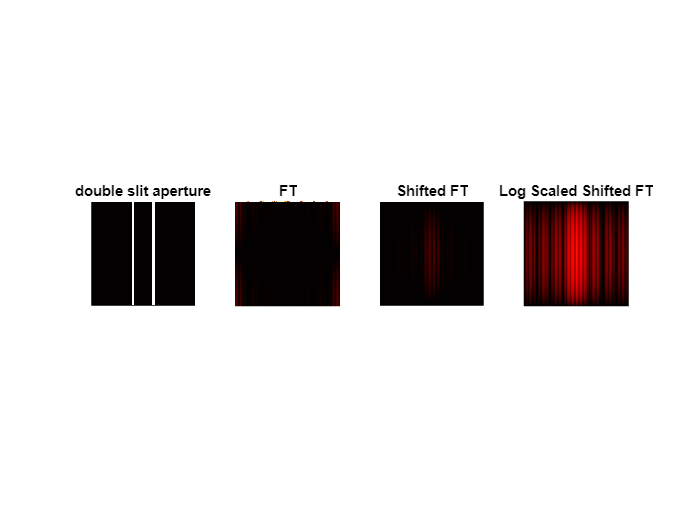


N = 400;
x = linspace(-1, 1, N);
y = x;
[X, Y] = meshgrid(x, y);
A = zeros(size(X));                 
A(abs(X+0.2) < 0.02 & abs(Y) < 1) = 1.0;
A(abs(X-0.2) < 0.02 & abs(Y) < 1) = 1.0;

figure;

FA = fft2(A);
FAshift = fftshift(FA);
FAshiftlog = rescale(log(abs(fftshift(FA))+1), 0,256); 

%plotting
figure;
subplot(1,4,1);imshow(A); title('double slit aperture');
subplot(1,4,2); image(abs(FA)); title('FT'); axis square; axis off;
subplot(1,4,3); image(abs(FAshift)); title('Shifted FT'); axis square; axis off;
subplot(1,4,4); imagesc(abs(FAshiftlog)); title('Log Scaled Shifted FT'); axis square; axis off; colormap hot;

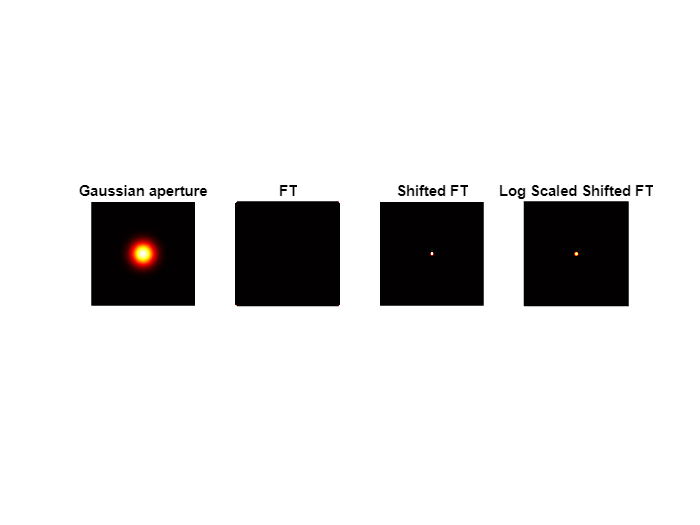

%gaussian aperture
N = 400;
x = linspace(-1, 1, N);
y = x;
[X, Y] = meshgrid(x, y);
sigma = 0.15;
A = exp(-(X.^2 + Y.^2)/(2*sigma^2));

FA = fft2(A);
FAshift = fftshift(FA);
FAshiftlog = rescale(log(abs(fftshift(FA))+1), 0,256); 

%plotting
figure;
subplot(1,4,1);imshow(A); title('Gaussian aperture');
subplot(1,4,2); image(abs(FA)); title('FT'); axis square; axis off;
subplot(1,4,3); image(abs(FAshift)); title('Shifted FT'); axis square; axis off;
subplot(1,4,4); imagesc(abs(FAshiftlog)); title('Log Scaled Shifted FT'); axis square; axis off; colormap hot;

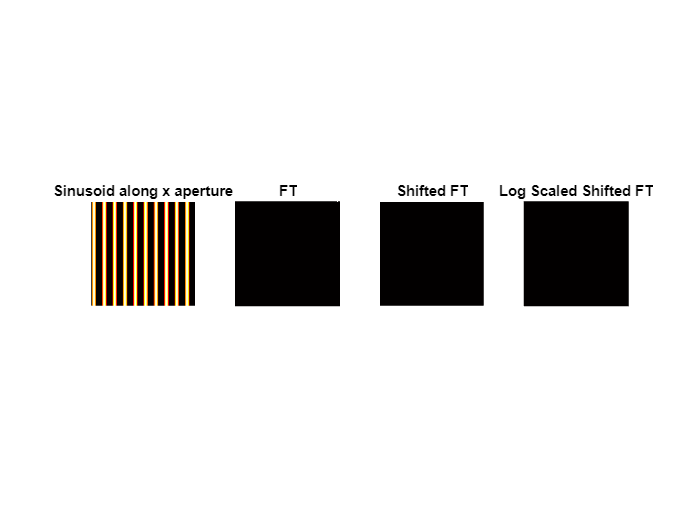

%sinusoid along x aperture
N = 400; % number of points in x and y directions
x = linspace(-1, 1, N); % x-axis
y = linspace(-1, 1, N); % y-axis
[X, Y] = meshgrid(x, y); % 2D grid of points
freq = 5; % frequency of sinusoid
A = sin(2*pi*freq*X); % sinusoid along x-axis

FA = fft2(A);
FAshift = fftshift(FA);
FAshiftlog = rescale(log(abs(fftshift(FA))+1), 0,256); 

%plotting
figure;
subplot(1,4,1);imshow(A); title('Sinusoid along x aperture');
subplot(1,4,2); imagesc(abs(FA)); title('FT'); axis square; axis off;
subplot(1,4,3); imagesc(abs(FAshift)); title('Shifted FT'); axis square; axis off;
subplot(1,4,4); imagesc(abs(FAshiftlog)); title('Log Scaled Shifted FT'); axis square; axis off; colormap hot;

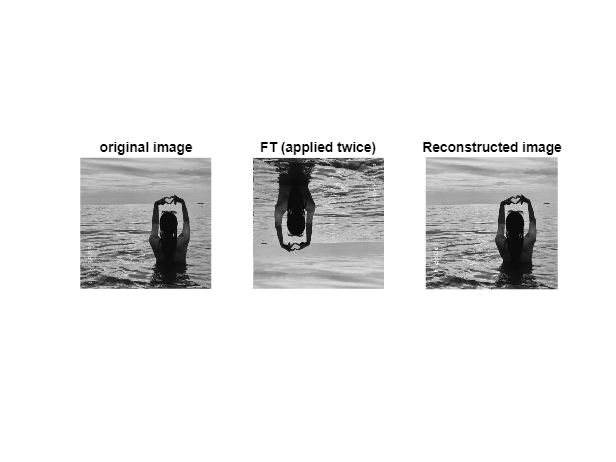

pic = rgb2gray(imread("square.jpg"));
FPic = fft2(pic);
F2Pic = fft2(FPic);
F2Pic_Inv = ifft2(FPic);

%plotting
figure;
subplot(1,3,1); imshow(pic); title('original image');
subplot(1,3,2); imagesc(abs(F2Pic)); axis off; axis square; title('FT (applied twice)');
subplot(1,3,3); imagesc(abs(F2Pic_Inv)); axis off; axis square; title('Reconstructed image'); colormap gray;

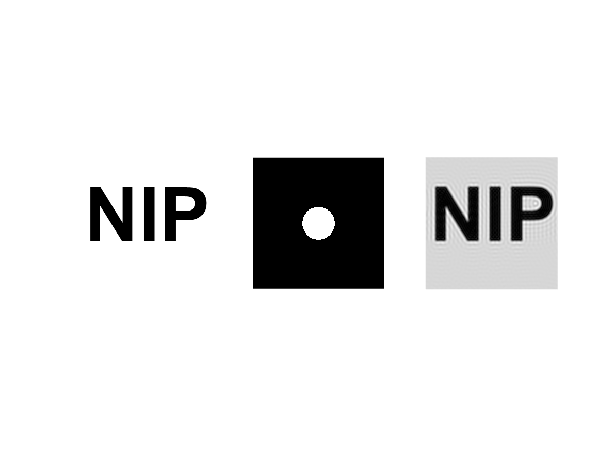

% Activity 2.2. Simulation of an imaging system (Convolution)

B = rgb2gray(imread('NIP2.tif')); 

N = 256; 
x = linspace(-1, 1, N);
y = x;
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);
A1 = zeros(size(R));                 
A1(R < 0.25) = 1.0;                   
   
Aperture = fftshift(A1);
FB = fft2(B(:,:,1));

multiply = FB.*Aperture;
inverted1 = ifft2(multiply);         

%plotting
figure;
subplot(1,3,1); imshow(B); 
subplot(1,3,2); imshow(A1);
subplot(1,3,3); imagesc(abs(inverted1)); axis square; axis off; colormap gray; 

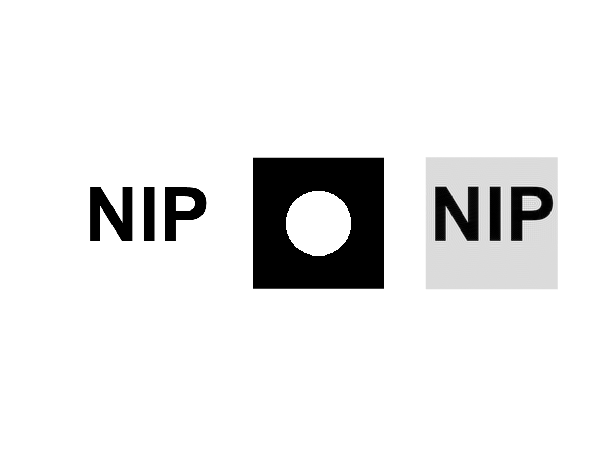

B = rgb2gray(imread('NIP2.tif')); 


N = 256; 
x = linspace(-1, 1, N);
y = x;
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);
A2 = zeros(size(R));                 
A2(R < 0.50) = 1.0;                  
   
Aperture = fftshift(A2);
FB = fft2(B(:,:,1));

multiply = FB.*Aperture;
inverted2 = ifft2(multiply);         

%plotting
figure;
subplot(1,3,1); imshow(B); 
subplot(1,3,2); imshow(A2);
subplot(1,3,3); imagesc(abs(inverted2)); axis square; axis off; colormap gray; 

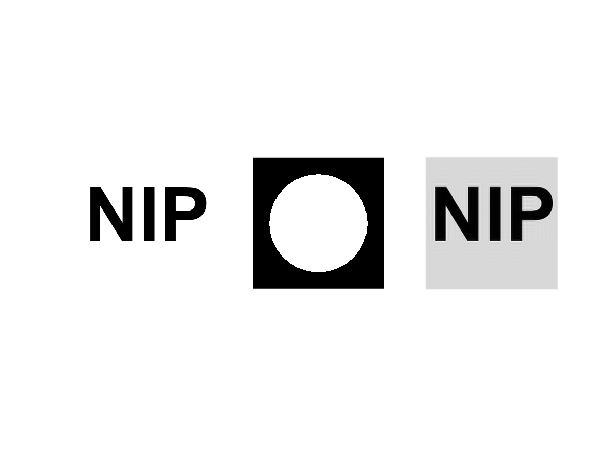

B = rgb2gray(imread('NIP2.tif')); 


N = 256; 
x = linspace(-1, 1, N);
y = x;
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);
A3 = zeros(size(R));                 
A3(R < 0.75) = 1.0;                  
   
Aperture = fftshift(A3);
FB = fft2(B(:,:,1));

multiply = FB.*Aperture;
inverted3 = ifft2(multiply);         

%plotting
figure;
subplot(1,3,1); imshow(B); 
subplot(1,3,2); imshow(A3);
subplot(1,3,3); imagesc(abs(inverted3)); axis square; axis off; colormap gray; 

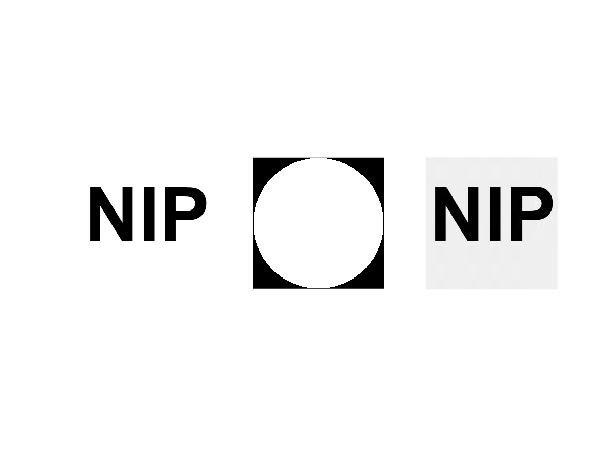

B = rgb2gray(imread('NIP2.tif')); 


N = 256; 
x = linspace(-1, 1, N);
y = x;
[X, Y] = meshgrid(x, y);
R = sqrt(X.^2 + Y.^2);
A4 = zeros(size(R));                 
A4(R < 1) = 1.0;                 
   
Aperture = fftshift(A4);
FB = fft2(B(:,:,1));

multiply = FB.*Aperture;
inverted4 = ifft2(multiply);        

%plotting
figure;
subplot(1,3,1); imshow(B); 
subplot(1,3,2); imshow(A4);
subplot(1,3,3); imagesc(abs(inverted4)); axis square; axis off; colormap gray; 

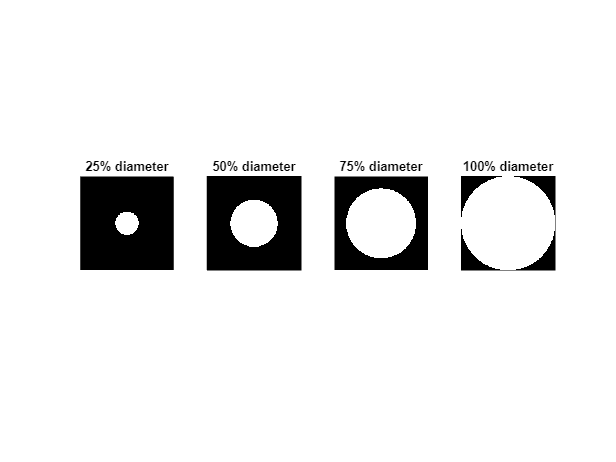

figure;
subplot(1,4,1); imshow(A1);; axis square; axis off; title('25% diameter');
subplot(1,4,2); imshow(A2); axis square; axis off; title('50% diameter');
subplot(1,4,3); imshow(A3); axis square; axis off; title('75% diameter');
subplot(1,4,4); imshow(A4); axis square; axis off;title('100% diameter'); colormap gray;

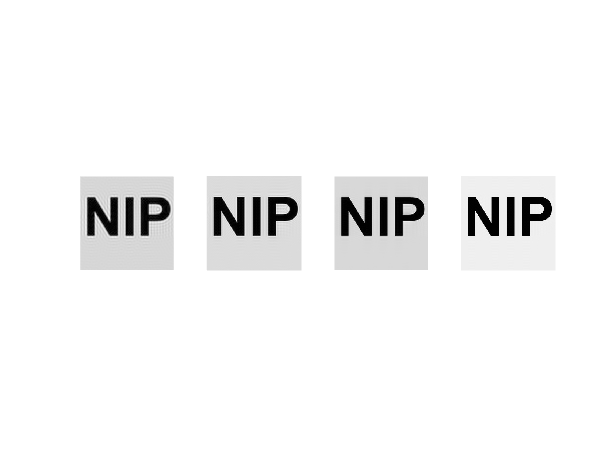

figure;
subplot(1,4,1); imagesc(abs(inverted1)); axis square; axis off;
subplot(1,4,2); imagesc(abs(inverted2)); axis square; axis off;
subplot(1,4,3); imagesc(abs(inverted3)); axis square; axis off;
subplot(1,4,4); imagesc(abs(inverted4)); axis square; axis off; colormap gray; 

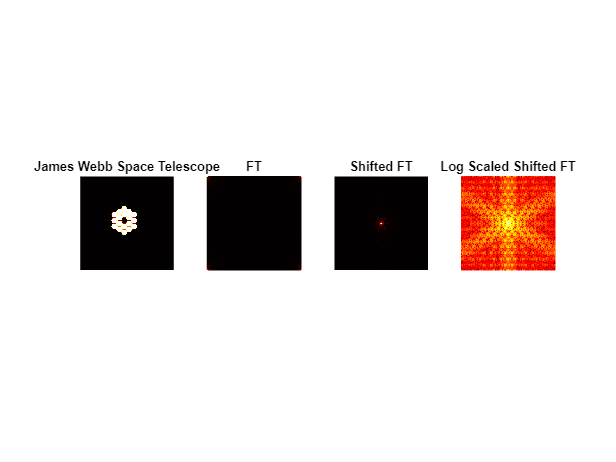


JWST = rgb2gray(imread("Copy of JWST Primary Mirror.png"));
FJWST = fft2(JWST);
FAshiftJ = fftshift(FJWST);
FAshiftlogJ = rescale(log(abs(fftshift(FJWST))+1), 0,256); 

%plotting
figure;
subplot(1,4,1);imshow(JWST); title('James Webb Space Telescope');
subplot(1,4,2); imagesc(abs(FJWST)); title('FT'); axis square; axis off;
subplot(1,4,3); imagesc(abs(FAshiftJ)); title('Shifted FT'); axis square; axis off;
subplot(1,4,4); imagesc(abs(FAshiftlogJ)); title('Log Scaled Shifted FT'); axis square; axis off; colormap hot;

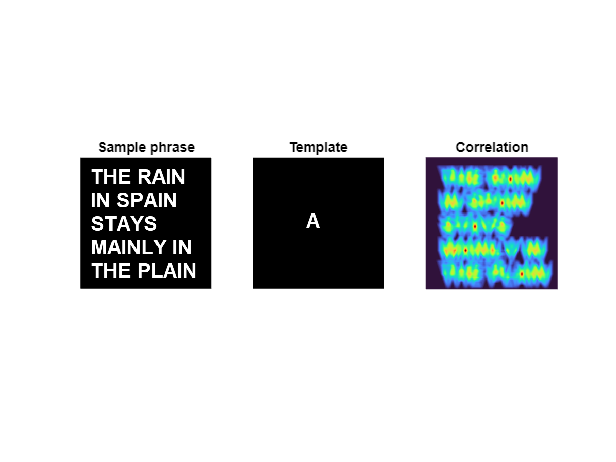


% Activity 2.3. Template matching using correlation 
C = rgb2gray(imread('The rain.png'));
A = rgb2gray(imread("A.png"));

CFFT= fft2(C);
AFFT = fft2(A);

P = conj(AFFT).*CFFT;
smallp = ifft2(P);
smallpp = fftshift(smallp);

%plotting
figure;
subplot(1,3,1); imshow(C); title('Sample phrase');
subplot(1,3,2); imshow(A); title('Template');
subplot(1,3,3);  imagesc(abs(smallpp)); axis image; axis off; title('Correlation'); colormap gray;
ax1 = subplot(1,3,3); colormap(ax1,turbo) 

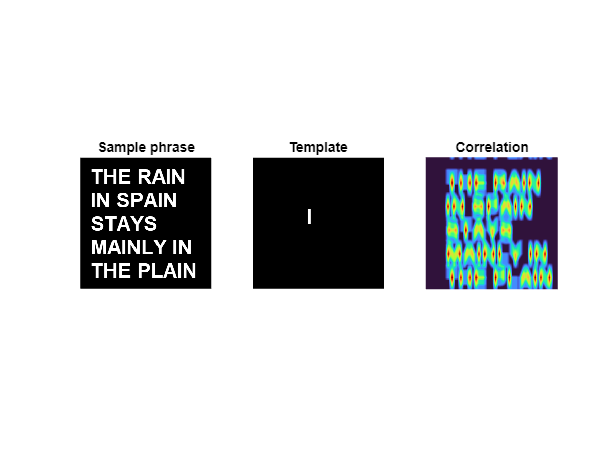


C = rgb2gray(imread('The rain.png'));
I = rgb2gray(imread("I.png"));

CFFT= fft2(C);
IFFT = fft2(I);

P = conj(IFFT).*CFFT;
smallp = ifft2(P);
smallpp = fftshift(smallp);

%plotting
figure;
subplot(1,3,1); imshow(C); title('Sample phrase');
subplot(1,3,2); imshow(I); title('Template');
subplot(1,3,3);  imagesc(abs(smallpp)); axis image; axis off; title('Correlation'); colormap gray;
ax1 = subplot(1,3,3); colormap(ax1,turbo) 